# Datetime Selector

This widget provides a combined date and time selection. It's value uses a datetime object.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 350 250]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);
gridObj.RowHeight = 30;

Create and configure the widget:

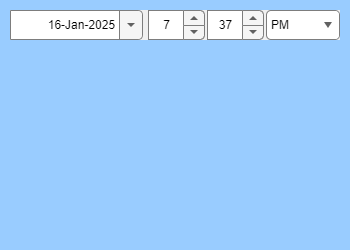

dateWidget =   DatetimeSelector with properties:

       ValueChangedFcn: @(src,evt)disp(evt)

                 Value: 16-Jan-2025 19:37:37
              ShowAMPM: on
           ShowSeconds: off
          ShowTimeZone: off
            DateFormat: 'dd-MMM-uuuu'
    DisabledDaysOfWeek: []
         DisabledDates: [0×0 datetime]
                Limits: [01-Jan-0000    31-Dec-9999]
            FieldColor: [1 1 1]

              Position: [11 211 330 30]
                 Units: 'pixels'

  Show all properties


dateWidget = wt.DatetimeSelector(gridObj);
dateWidget.ValueChangedFcn = @(src,evt)disp(evt);
dateWidget.Value = datetime("now","TimeZone","local")

Change some display settings:

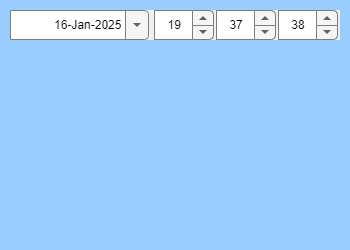

dateWidget.ShowSeconds = "on";
dateWidget.ShowAMPM = "off";

Change the calendar settings:

dateWidget.DisabledDaysOfWeek = ["Saturday" "Sunday"];

Focus to the date control and open it (newer releases only):

dateWidget.focusDateControl();

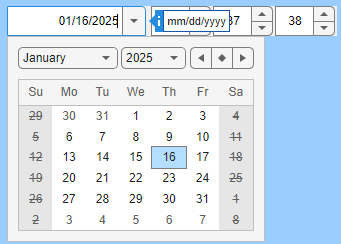

*Copyright 2020-2025 The MathWorks, Inc.*